## SIOC 221A HW 7

## Kevin Okun

% Pulling functions from GitHub. Working with Ben Werb
clear

% Load data
load('/Users/kevinokun/Documents/GitHub/SIO221a_Github_code/class10_coding_github_exercise/class10_record');

% Convert number of points to number of chunks
number_of_points = 8000;
number_of_chunks = floor(length(class10_record.data)/number_of_points);

% Get fft of data from both functions
[KO_fft,KO_freq] = Okun_Lecture10(class10_record.data,class10_record.time,number_of_chunks);

The variance of the data is 0.0038496 and the variance of the spectrum is 0.0038496
The ratio of the variance of the data to the spectrum is 1


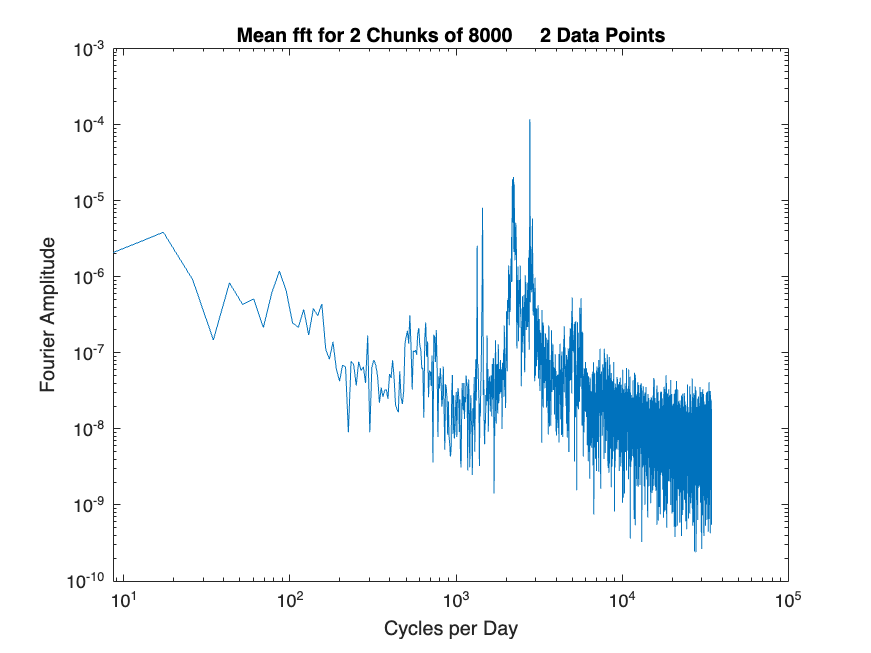


BW_Data = Class10_Ben(number_of_points);

disp(['The ratio of the variance of the data to the spectrum is ' num2str(BW_Data.p)])

The ratio of the variance of the data to the spectrum is 0.99997


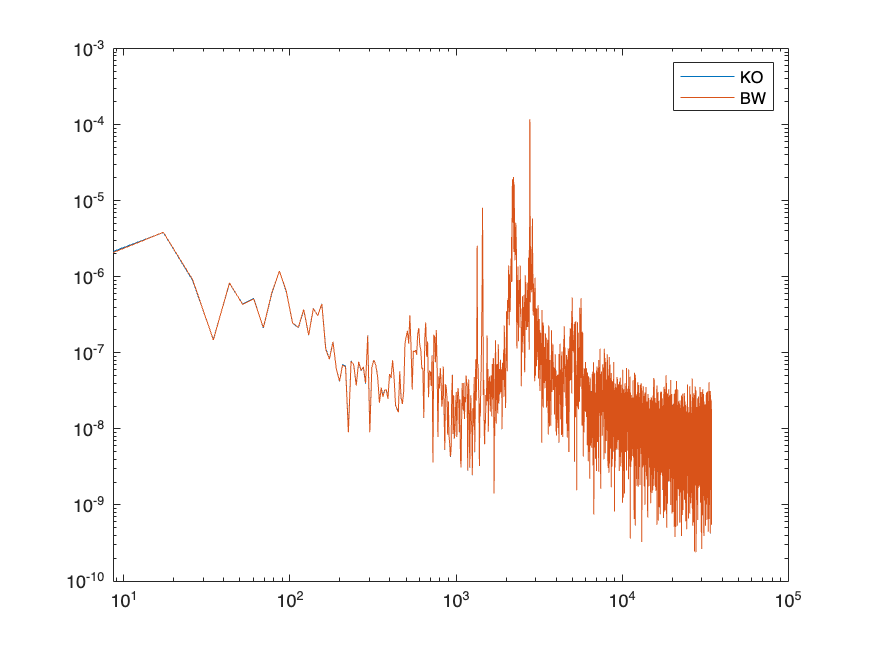


figure
loglog(KO_freq,KO_fft)
hold on
loglog(BW_Data.f_vector,BW_Data.spectra)
legend('KO','BW')

For my project, I will be working with a 10 year time series of ADCP data from three locations along the 33m isobath in San Diego. This data is the basis for the first chapter of my thesis. I will be demonstrating using spectral methods that the primary along-shore currents in the area are driven by the M2 tidal constituent and will show how this manifests on the shelf.